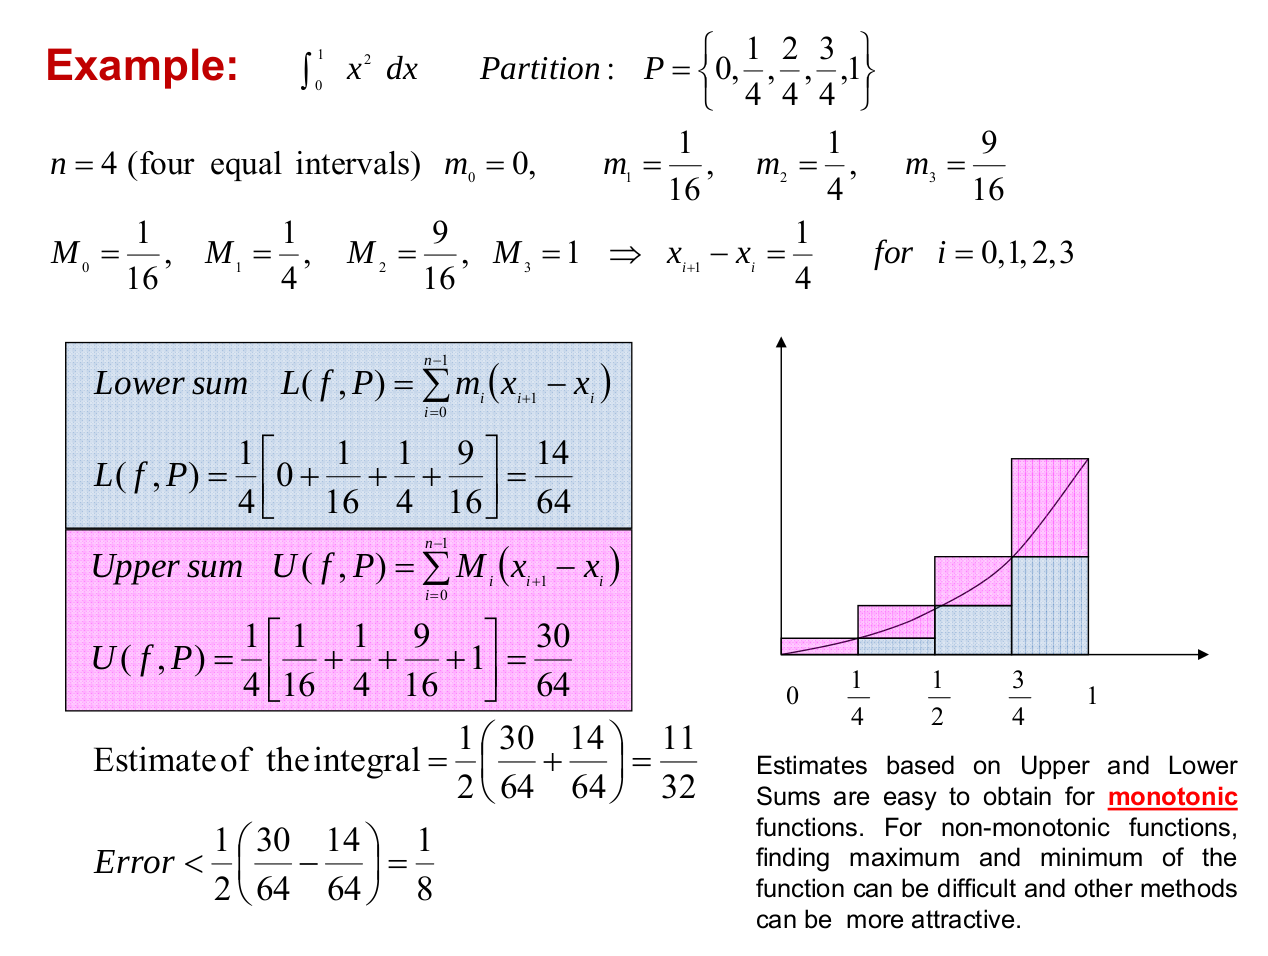

clear;clf;
p = [0 1/4 2/4 3/4 1]

p =                    0   0.250000000000000   0.500000000000000   0.750000000000000   1.000000000000000


f = @(x)(x^2);
%Lower sum
n = length(p);
sumary = 0;
for i=1:n-1;
    %delta*high
    sumary = sumary + (p(i+1)-p(i))*f(p(i));
end
disp('Lower sum')

Lower sum


sumary

sumary =    0.218750000000000



LowerSum(f,p);

Lower sum is 0.21875




%Uper sum
n = length(p);
sumary = 0;
for i=1:n-1;
    %delta*high
    sumary = sumary + (p(i+1)-p(i))*f(p(i+1));
end
disp('Uper sum')

Uper sum


sumary

sumary =    0.468750000000000



UpperSum(f,p);

Upper sum is 0.46875


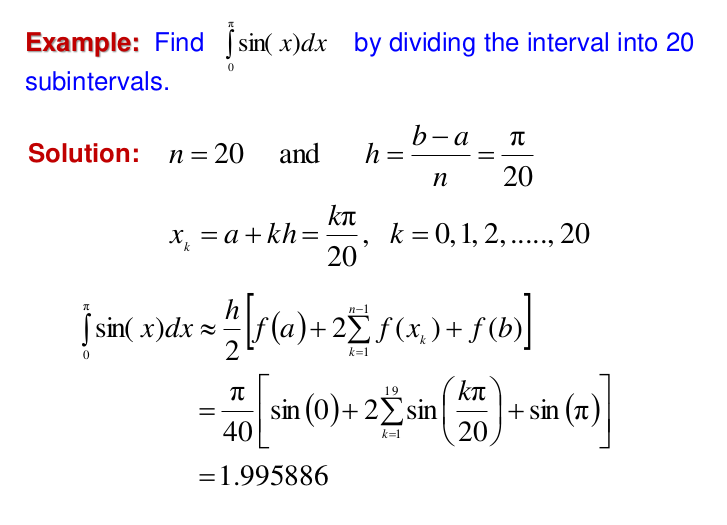

f = @(x)(sin(x))

f = function_handle with value:
    @(x)(sin(x))


TrapComp(f,0,pi,20)

ans =    1.995885972708715


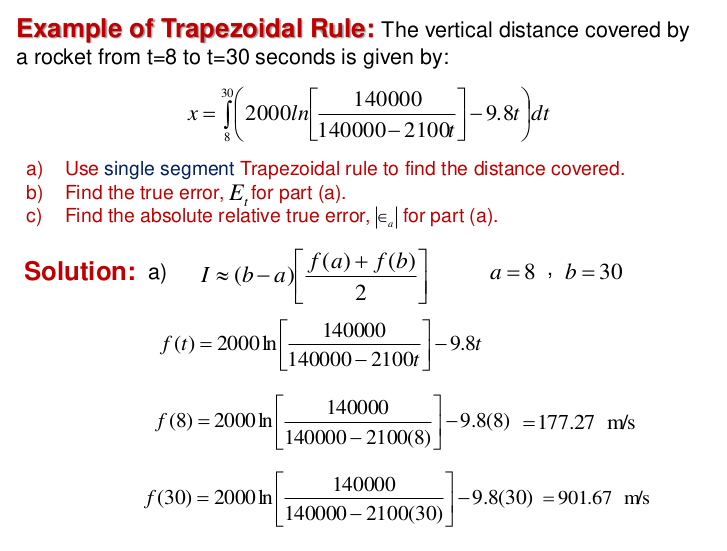

clear;clf;
f = @(t)(2000.*ln(14e4./(14e4-2100.*t))-9.8.*t);
disp('a) Trap comp')

a) Trap comp


Sim_var = TrapComp(f,8,30,1)

y =    0.127833371509885   0.597837000755620


Sim_var =      1.186834818984112e+04



disp('b) ')

b) 


disp('integral')

integral


t_var = integral(f,8,30)

y =    0.127833576793965   0.127840643566968   0.127884502278958   0.128019662286543   0.128308684472064   0.128807050161351   0.129553375724811   0.130555824022994   0.131778689545977   0.133145597477648   0.134557185629007   0.135900761419717   0.137048775507404   0.137874169509928   0.138301622925527   0.138476487652155   0.138915651291578   0.139813957999948   0.141187838507134   0.143017770336528   0.145275045909088   0.147920448323927   0.150878123818097   0.154019068188897   0.157180411983943   0.160196790044364   0.162903104027253   0.165118510860877   0.166666018399272   0.167454337495600   0.167774427573376   0.168572469313368   0.170180513387118   0.172583440814676   0.175693503351800   0.179411806096846   0.183634010205887   0.188213882498792   0.192944416107069   0.197590717034768   0.201932864934491   0.205762967504179   0.208857107726412   0.210998265391508   0.212082982421320   0.212522300854560   0.213614843654070   0.215804726552218   0.219049792398680   0.22320481141

t_var =      1.106133553508099e+04


E = t_var - Sim_var

E =     -8.070126547601267e+02



disp('c) ')

c) 


abs(E/t_var*100)

ans =    7.295797620465345


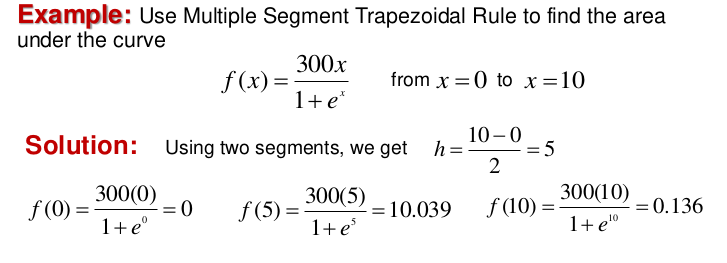

clear;clf;clc 
f = @(x)((300*x)./(1+exp(x)));
f(5)

ans =   10.039276386427284


TrapComp(f,0,10,1000)

ans =      2.465890424838389e+02


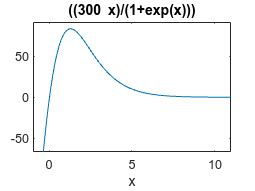

ezplot(f,[-1 11])

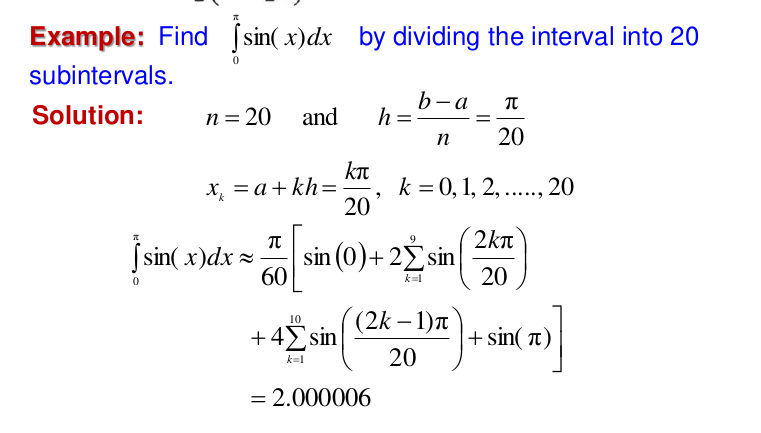

clear;clf;
f = @(x)(sin(x))

f = function_handle with value:
    @(x)(sin(x))


Simpson(f,0,pi,20)

ans =    2.000006784441801


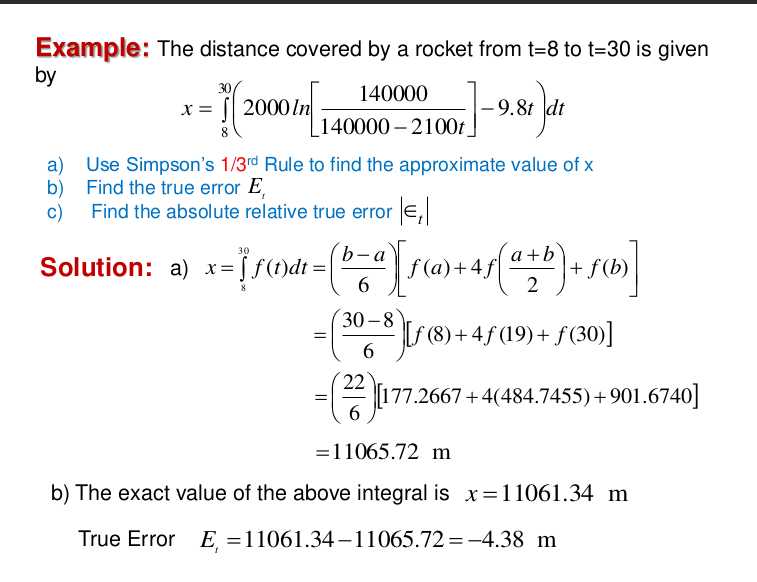

clear;clf;
f = @(t)(2000.*ln(14e4./(14e4-2100.*t))-9.8.*t);
disp('a) Trap comp')

a) Trap comp


Sim_var = Simpson(f,8,30,4)

y =    0.127833371509885


y =    0.226273444323138


y =    0.335472736288129


y =    0.335472736288129


y =    0.458075058380462


y =    0.597837000755620


Sim_var =      1.106163613740592e+04



disp('b) ')

b) 


disp('integral')

integral


t_var = integral(f,8,30)

y =    0.127833576793965   0.127840643566968   0.127884502278958   0.128019662286543   0.128308684472064   0.128807050161351   0.129553375724811   0.130555824022994   0.131778689545977   0.133145597477648   0.134557185629007   0.135900761419717   0.137048775507404   0.137874169509928   0.138301622925527   0.138476487652155   0.138915651291578   0.139813957999948   0.141187838507134   0.143017770336528   0.145275045909088   0.147920448323927   0.150878123818097   0.154019068188897   0.157180411983943   0.160196790044364   0.162903104027253   0.165118510860877   0.166666018399272   0.167454337495600   0.167774427573376   0.168572469313368   0.170180513387118   0.172583440814676   0.175693503351800   0.179411806096846   0.183634010205887   0.188213882498792   0.192944416107069   0.197590717034768   0.201932864934491   0.205762967504179   0.208857107726412   0.210998265391508   0.212082982421320   0.212522300854560   0.213614843654070   0.215804726552218   0.219049792398680   0.22320481141

t_var =      1.106133553508099e+04


E = t_var - Sim_var

E =   -0.300602324930878



disp('c) ')

c) 


abs(E/t_var*100)

ans =    0.002717595212418


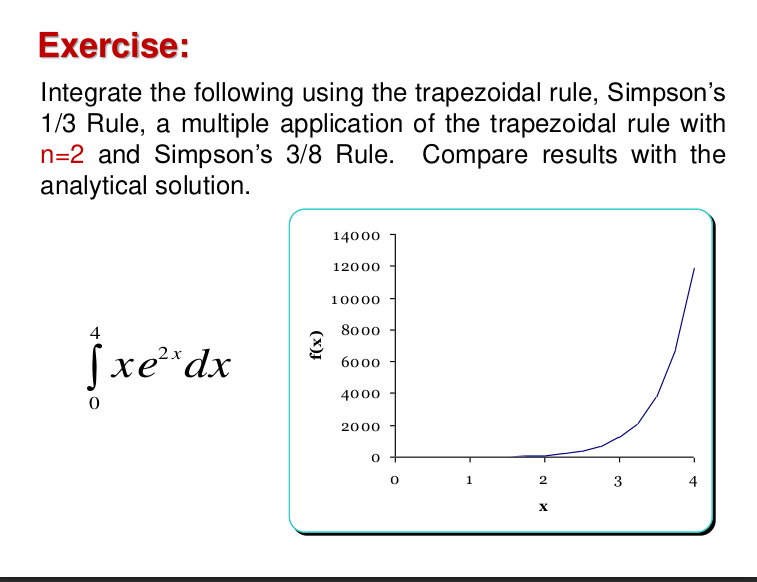

clear;clf;
f = @(x)(x.*exp(2.*x));
disp('integral')

integral


integral(f,0,4)

ans =      5.216926477323024e+03


disp('Simpson')

Simpson


Simpson(f,0,4,2)

ans =      8.240411432288045e+03


disp('TrapComp 1/3')

TrapComp 1/3


TrapComp(f,0,4,2)

ans =      1.214222454829949e+04


disp('TrapComp 3/8')

TrapComp 3/8


disp('Error 404 not found')

Error 404 not found


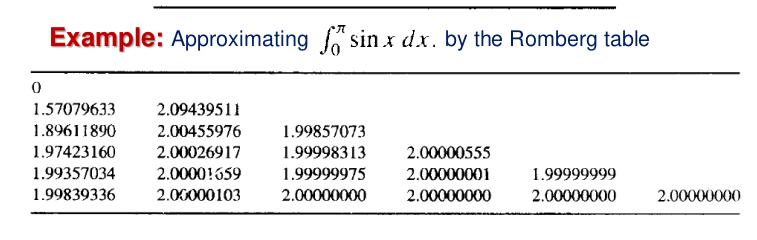

clear;clc;clf;
f = @(x)(sin(x));
Romberg(f,0,pi,pi,6)

ans =    1.821328415663512   1.990704584762647   1.989991433704000   2.004233853796907   1.999556567787790   1.999867252820244
   1.948360542487863   1.990036005645165   2.004011315982955   1.999574838436263   1.999866949416892                   0
   1.979617139855840   2.003137859086843   1.999644158397930   1.999865808358374                   0                   0
   1.997257679279092   1.999862514690987   1.999862345077742                   0                   0                   0
   1.999211305838013   1.999862355678570                   0                   0                   0                   0
   1.999699593218431                   0                   0                   0                   0                   0


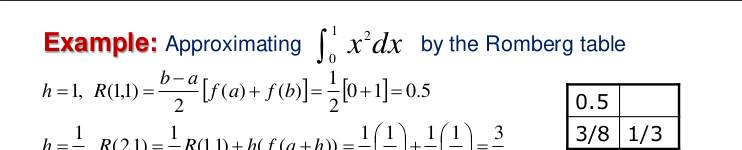

clear;clc;clf;
f = @(x)(x.^2);
Romberg(f,0,1,1,3)

ans =    0.500000000000000   0.333333333333333   0.333333333333333
   0.375000000000000   0.333333333333333                   0
   0.343750000000000                   0                   0


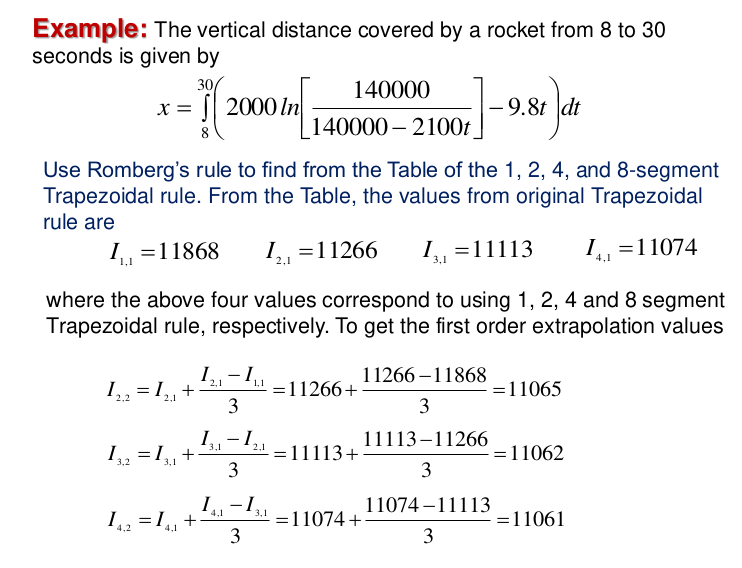

clear;clf;
f = @(t)(2000.*ln(14e4./(14e4-2100.*t))-9.8.*t);
Romberg(f,8,30,30,5)

y =    0.127833371509885   0.140412153716745   0.153151179494175   0.166054584330083   0.179126665897435   0.192371892647456   0.205794912979597   0.219400565035375   0.233193887167711   0.247180129142451   0.261364764134408   0.275753501586507   0.290352301007660   0.305167386792800   0.320205264157341   0.335472736288129   0.350976922824095   0.366725279792234   0.382725621138675   0.398986142010455   0.415515443961666   0.432322562278047   0.449416995637347   0.466808738349216   0.484508315448617   0.502526820951296   0.520875959619492   0.539568092631645   0.558616287602339   0.578034373459441   0.597837000755620


y =    0.127833371509885   0.134102984523480   0.140412153716745   0.146761381395404   0.153151179494175   0.159582069824465   0.166054584330083   0.172569265351276   0.179126665897435   0.185727349928788   0.192371892647456   0.199060880798253   0.205794912979597   0.212574599964976   0.219400565035375   0.226273444323138   0.233193887167711   0.240162556483805   0.247180129142451   0.254247296365544   0.261364764134408   0.268533253613020   0.275753501586507   0.283026260915587   0.290352301007660   0.297732408305282   0.305167386792800   0.312658058521958   0.320205264157341   0.327809863542560   0.335472736288129   0.343194782382040   0.350976922824095   0.358820100285121   0.366725279792234   0.374693449441411   0.382725621138675   0.390822831371294   0.398986142010455   0.407216641146971   0.415515443961666   0.423883693632182   0.432322562278047   0.440833251945956   0.449416995637347   0.458075058380462   0.466808738349216   0.475619368031371   0.484508315448617   0.49347698543

y =    0.127833371509885   0.130963264518813   0.134102984523480   0.137252593426377   0.140412153716745   0.143581728478024   0.146761381395404   0.149951176763504   0.153151179494175   0.156361455124423   0.159582069824465   0.162813090405912   0.166054584330083   0.169306619716460   0.172569265351276   0.175842590696245   0.179126665897435   0.182421561794288   0.185727349928788   0.189044102554781   0.192371892647456   0.195710793912971   0.199060880798253   0.202422228500958   0.205794912979597   0.209179010963837   0.212574599964976   0.215981758286590   0.219400565035375   0.222831100132165   0.226273444323138   0.229727679191225   0.233193887167711   0.236672151544036   0.240162556483805   0.243665187035007   0.247180129142451   0.250707469660419   0.254247296365544   0.257799697969911   0.261364764134408   0.264942585482292   0.268533253613020   0.272136861116319   0.275753501586507   0.279383269637086   0.283026260915587   0.286682572118697   0.290352301007660   0.29403554642

y =    0.127833371509885   0.129397093486068   0.130963264518813   0.132531892291439   0.134102984523480   0.135676548970911   0.137252593426377   0.138831125719426   0.140412153716745   0.141995685322389   0.143581728478024   0.145170291163162   0.146761381395404   0.148355007230682   0.149951176763504   0.151549898127201   0.153151179494175   0.154755029076149   0.156361455124423   0.157970465930124   0.159582069824465   0.161196275179006   0.162813090405912   0.164432523958215   0.166054584330083   0.167679280057085   0.169306619716460   0.170936611927391   0.172569265351276   0.174204588692007   0.175842590696245   0.177483280153705   0.179126665897435   0.180772756804104   0.182421561794288   0.184073089832761   0.185727349928788   0.187384351136417   0.189044102554781   0.190706613328395   0.192371892647456   0.194039949748153   0.195710793912971   0.197384434471000   0.199060880798253   0.200740142317973   0.202422228500958   0.204107148865877   0.205794912979597   0.20748553045

y =    0.127833371509885   0.128614926844705   0.129397093486068   0.130179872391008   0.130963264518813   0.131747270831021   0.132531892291439   0.133317129866141   0.134102984523480   0.134889457234094   0.135676548970911   0.136464260709160   0.137252593426377   0.138041548102409   0.138831125719426   0.139621327261927   0.140412153716745   0.141203606073057   0.141995685322389   0.142788392458628   0.143581728478024   0.144375694379201   0.145170291163162   0.145965519833300   0.146761381395404   0.147557876857664   0.148355007230682   0.149152773527480   0.149951176763504   0.150750217956637   0.151549898127201   0.152350218297970   0.153151179494175   0.153952782743511   0.154755029076149   0.155557919524740   0.156361455124423   0.157165636912837   0.157970465930124   0.158775943218941   0.159582069824465   0.160388846794405   0.161196275179006   0.162004356031060   0.162813090405912   0.163622479361470   0.164432523958215   0.165243225259203   0.166054584330083   0.16686660223

ans = 1.0e+04 *

   1.106225217711561   1.106133554123879   1.106133553508104   1.106133553508100   1.106133553508099
   1.106156470020800   1.106133553546591   1.106133553508100   1.106133553508099                   0
   1.106139282665143   1.106133553510505   1.106133553508099                   0                   0
   1.106134985799165   1.106133553508249                   0                   0                   0
   1.106133911580978                   0                   0                   0                   0


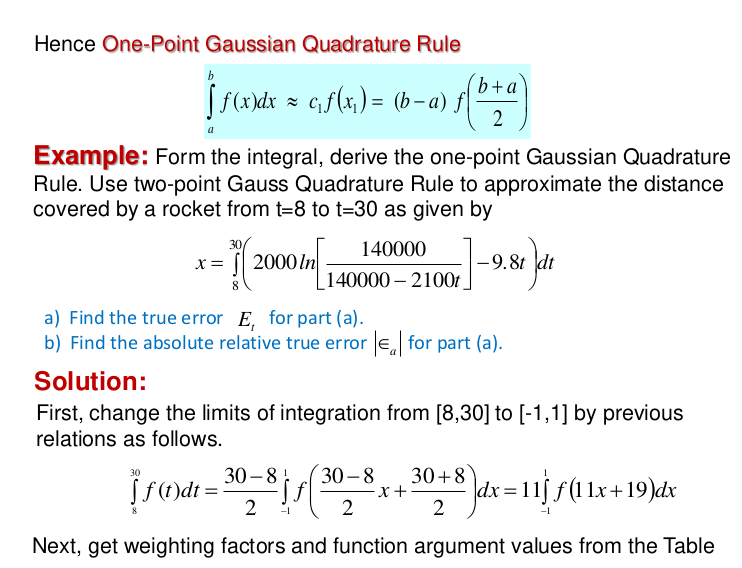

clear;clf;
f = @(x)(2000.*ln(14e4./(14e4-2100.*x))-9.8.*x);
a = 8;
b = 30;
c1 = 1;
c2 = 1

c2 =      1


x1 = -0.577350269;
x2 = 0.577350269;

(b-a)/2*(c1*f(11*x1+19)+c2*f(11*x2+19))

y =    0.210396646421776


y =    0.478459752709142


ans =      1.105844078088019e+04


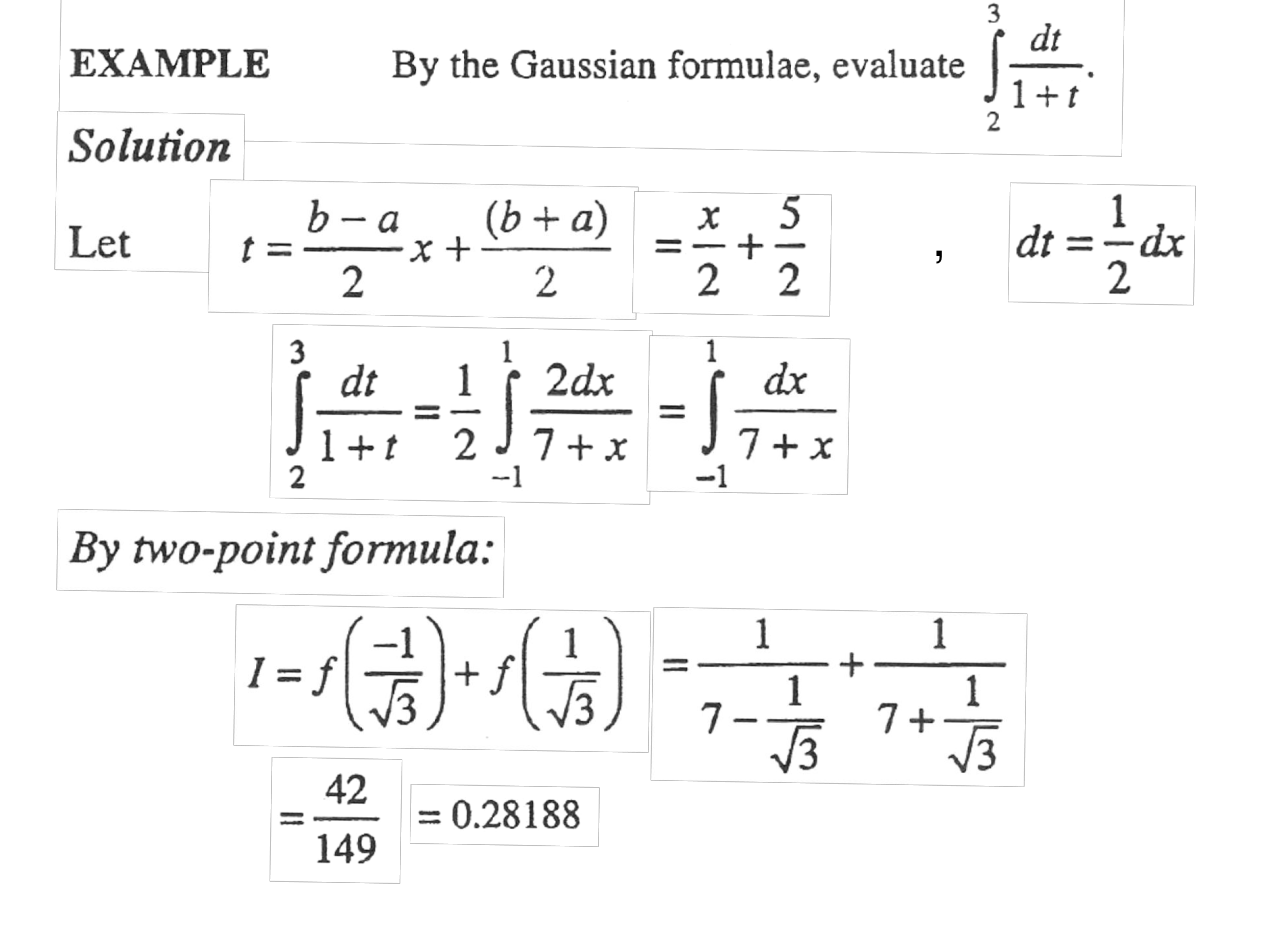

clear;clf;clf;
f = @(x)(1./(1+x));

GaussInt(f,2,3,2)

ans =    0.287671232875418


integral(f,2,3)

ans =    0.287682072451781


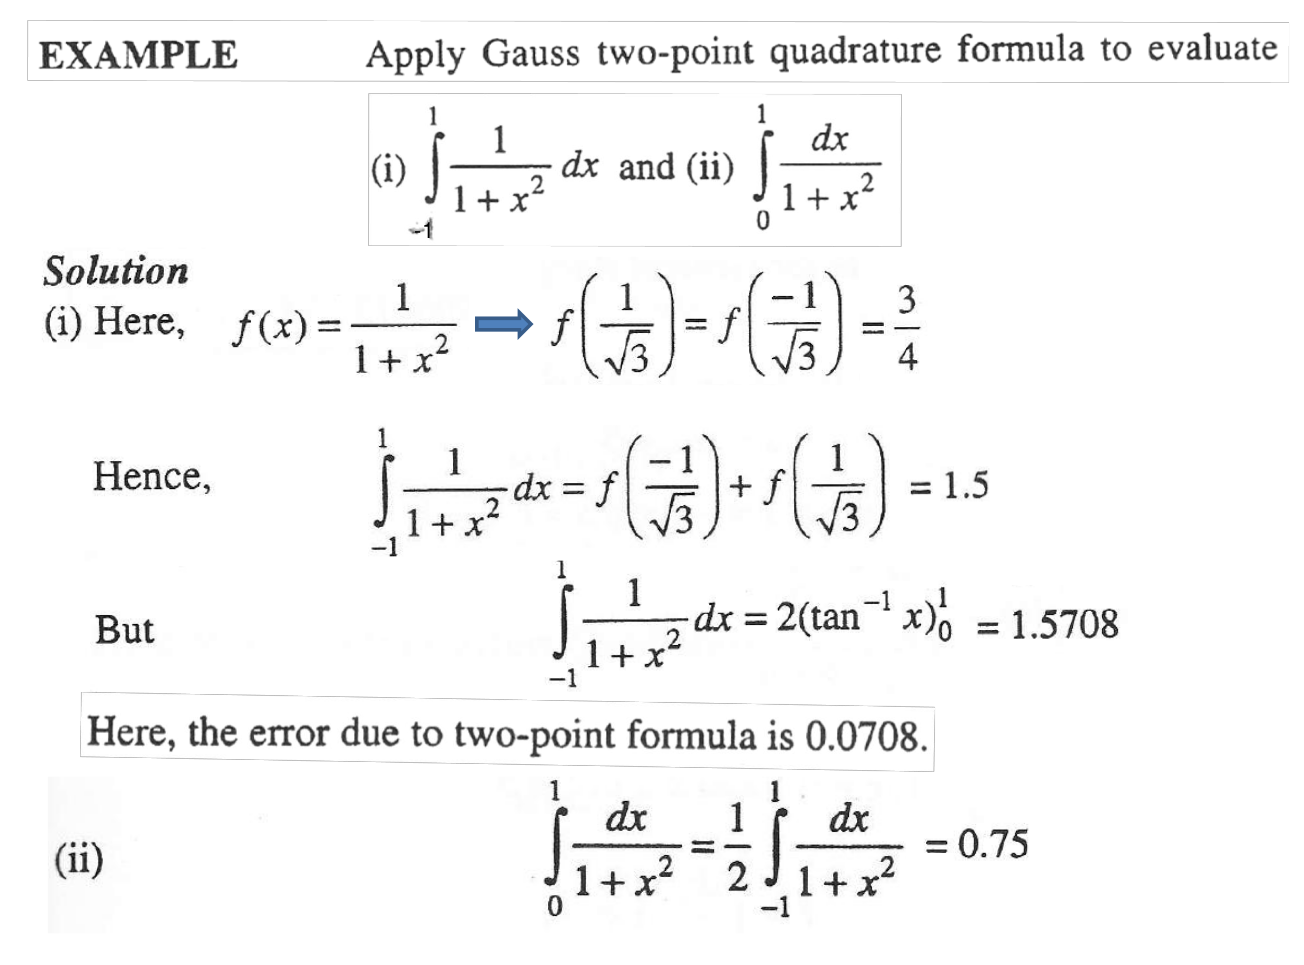

clear;clf;
f = @(x)(1./(1+x.^2))

f = function_handle with value:
    @(x)(1./(1+x.^2))


GaussInt(f,-1,1,2)

ans =    1.500000000246331


GaussInt(f,-1,1,6)

ans =    1.570731707938815



GaussInt(f,0,1,2)

ans =    0.786885245911702


GaussInt(f,0,1,6)

ans =    0.785398152828429


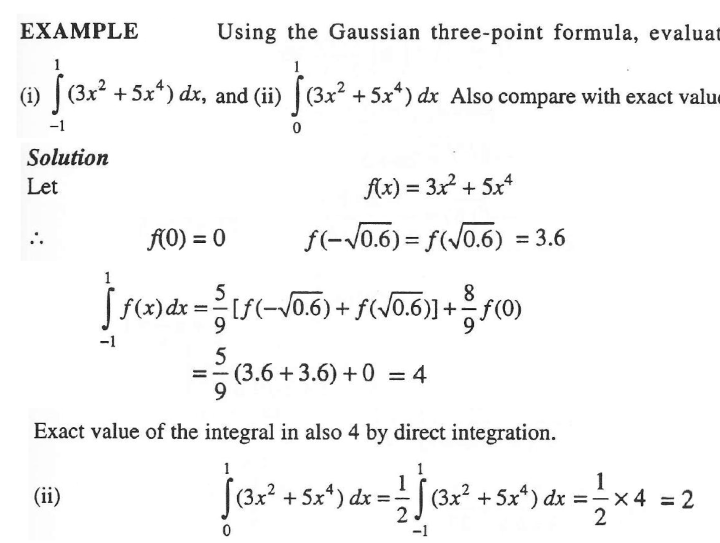

clear;clf;
f = @(x)(3.*x.^2+5.*x.^4)

f = function_handle with value:
    @(x)(3.*x.^2+5.*x.^4)


GaussInt(f,-1,1,3)

ans =    3.999999999458955




GaussInt(f,0,1,3)

ans =    2.000000000657743


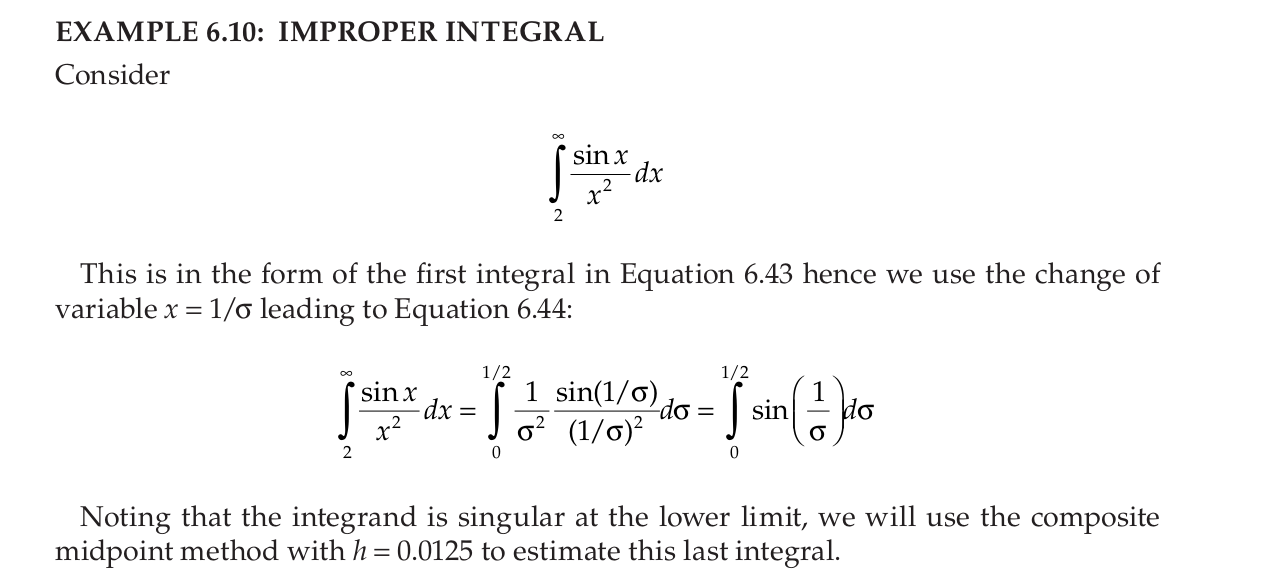

clear;clf;clf;
% Use s to represent sigma
f = @(s)(sin(1/s)); 
h = 0.0125; 
s = 0:h:0.5;

n = length(s)-1; 
m = zeros(n,1); 

I = 0;
for i = 1:n,
    m(i) = (s(i+1)+s(i))/2;
    I = I + f(m(i));
end
I = I*h

I =    0.027687112368230
